# 実践ロバスト制御　第2章演習問題

clear; close all; clc;

## 問題1

**次の伝達関数の**$H_{\infty}$**ノルムを定義から求めよ。**


$$G_1 = \frac{1}{3s+5}\text{、} G_2 = \frac{1}{s^2+s+1}$$


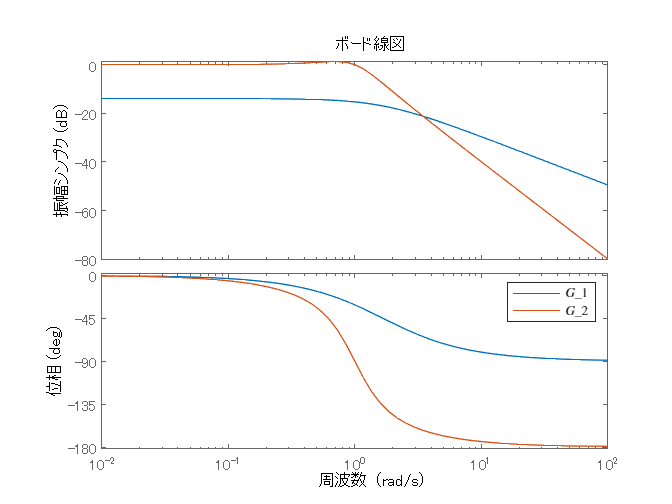

s = tf("s");
G1 = 1/(3*s+5);
G2 = 1/(s^2+s+1);
figure;
bode(G1,G2);
legend("$G_1$", "$G_2$","Interpreter","latex");

G1_hinfnorm = hinfnorm(G1)

G1_hinfnorm = 0.2000

G2_hinfnorm = hinfnorm(G2)

G2_hinfnorm = 1.1547

## 問題2

**図2.1の一般化プラントについて、つぎの各問いに答えよ。**

**1. **$w$**から**$z$**までの閉ループ伝達関数**$G_{zw}$**が**


$$G_{zw}=\frac{PK}{1+PK}W$$


**となるように一般化プラント**$G$**を構成し、**$G$**の伝達行列表現を求めよ。ただし、**$P$**は1入出力の制御対象、**$K$**はフィードバック制御器、**$W$**は重み関数とする。なお、**$w$**は**$P$**の出力端に加えるものとし、**$P$**は虚軸上に極および零点を持たず、**$W$**は安定で虚軸上に零点を持たないものとする。**

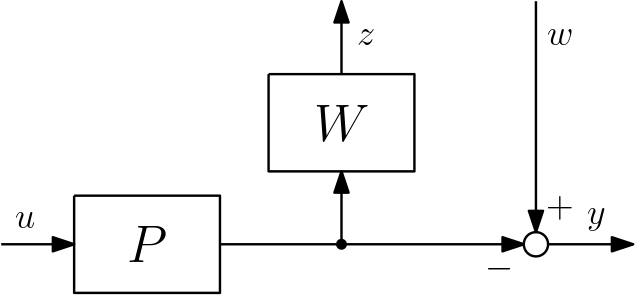


$$G=\pmatrix{0 & PW\cr 1 & -P}$$


**2. 上記1.で求めた一般化プラントは、標準**$H_{\infty}$**制御問題の仮定A1~A4を満たすかどうか考察し、満たさない場合は、満たすように修正せよ。**

**なお、一般化プラント**$G$**の状態空間実現は**


$$\dot{x}(t) = Ax(t)+B_1w(t)+B_2u(t)\\
z(t) = C_1x(t)+D_{11}w(t)+D_{12}u(t)\\
y(t) = C_2x(t)+D_{21}w(t)$$


**で一般化でき、ドイルの記号法を使って、**


$$G=\pmatrix{G_{11} & G_{12}\cr G_{21} & G_{22}} = 
\left(\begin{array}{c|cc}
A & B_1 & B_2 \\ 
\hline 
C_1 & D_{11} & D_{12} \\ 
C_2 & D_{21} & O 
\end{array}\right)$$


**と記述できる。**

**仮定A1**:$(A,B_2)$は可安定、かつ、$(C_2,A)$は可検出（*実際の制御対象が可安定、可検出であることに加えて、重み関数が全て安定）

両方とも〇。$P$に加え$W$も安定。

**仮定A2**:$D_{12}$は縦長列フルランク、かつ、$D_{21}$は横長行フルランク

$D_{12}$は×。$P$は厳密にプロパなため、$u$から$z$の直達項が$0$であるため。

$D_{21}$は〇。$w$から$y$の直達項が$1$であるため。

**仮定A3**:$G_{12}$は虚軸上に不変零点を持たない。

**仮定A4**:$G_{21}$は虚軸上に不変零点を持たない。

上記仮定は$P$および$W$が虚軸上に極および零点を持たない限り成立。仮に持っている場合でも、虚軸上で$(C_1,A)$が不可観測または虚軸上で$(A,B_1)$が不可制御でなければ大丈夫。

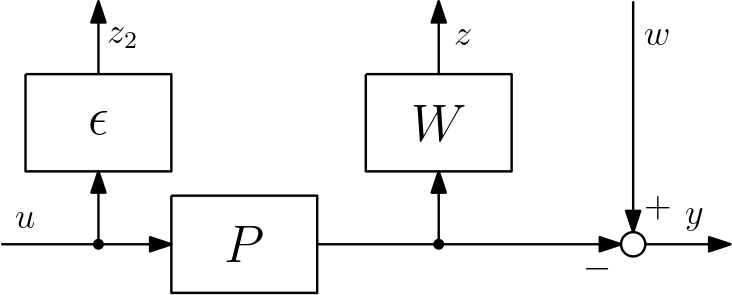

仮定A2の$D_{12}$が縦長列フルランクを満たさない場合は新たな制御量$z_i$を導入する。

仮定A2の$D_{21}$が横長行フルランクを満たさない場合は新たな外部入力$w_i$を導入する。

今回は前者のため、上図の様に新しい制御量$z_2$を導入する。

## 問題3

**図2.3の一般化プラントにおいて、**$P=10/(s+1)$**、**$W=1/(s+5)$**としたとき、つぎの各問いに答えよ。**

s = tf("s");
P = ss(-1,1,10,0);
W = ss(-5,1,1,0);

**1. 一般化プラント**$G$**の状態空間実現を求めよ。**

% sysicによる一般化プラントの定義
systemnames = 'P W';
inputvar    = '[w; u]';  % 入力信号の定義
outputvar   = '[P; P]';  % 出力信号の定義
input_to_P  = '[W - u]'; % Pへの入力を定義
input_to_W  = '[w]';     % Wへの入力を定義
G = sysic                % Gの計算

**2. 上記1.の結果を使って、**$W$**の極**$-5$**が**$G_{21}$($G_{12}$?)**の不変零点になることを、実際に計算して確かめよ。**

G12_invariant_zero = tzero(G(1,2))

**3. 制御器を定数ゲイン**$K=\alpha>0$**と仮定し、**$\|G_{zw}\|_{\infty}<1$**を満たす**$\alpha$**の範囲を求めよ。**

$G_{zw}=\frac{P}{1+PK}W$より、$P$、$W$および$K$を具体的に与えてノルム条件を求めると、次式より、


$$\left\|\frac{PW}{1+PK}\right\|_\infty = 
\left\|\frac{10}{(s+1+10\alpha)(s+5)}\right\|_\infty=\frac{2}{10\alpha+1}<1$$


$\alpha>0.1$となる。

alpha = 0.1;
K = alpha;
Gzw = P*W/(1+P*K);
Gzw_hinfnorm = hinfnorm(Gzw)

G =
 
  A = 
       x1  x2
   x1  -1   1
   x2   0  -5
 
  B = 
        w   u
   x1   0  -1
   x2   1   0
 
  C = 
         x1  x2
   [+P]  10   0
   [+P]  10   0
 
  D = 
         w  u
   [+P]  0  0
   [+P]  0  0
 
連続時間状態空間モデル。



G12_invariant_zero = -5

Gzw_hinfnorm = 1.0000

## 問題4

**一般化プラント**$G$**の伝達行列表現を次式で与えるとき、つぎの各問いに答えよ。ただし、**$P$**および**$M$**は安定かつプロパな1入出力の伝達関数とする。**


$$\pmatrix{z \cr y} = 
\underline{\pmatrix{M-P & P\cr P & -P}}_G
\pmatrix{w\cr u}$$


**1. 一般化プラント**$G$**のブロック線図を描け。**

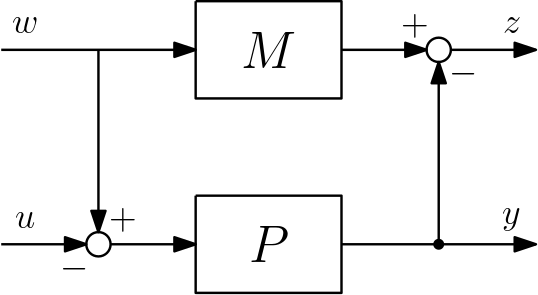

**2. 制御器**$K$**によって、フィードバック制御**$u=Ky$**を施した。このとき、**$w$**から**$z$**までの閉ループ伝達関数**$G_{zw}$**を求めよ。**


$$G_{zw} = M - \frac{P}{1+PK}$$


**3. **$G_{zw}$**の**$H_{\infty}$**ノルムが**$0$**になる制御器**$K$**が得られたとしよう。このとき、**$P$**、**$M$**、**$K$**の間に成り立つ関係式を書け。**

2.より$\|G_{zw}\|_{\infty}=0\Leftrightarrow 
G_{zw}=0$を計算して、


$$M=\frac{P}{1+PK}$$


## 問題5

**式(2.35)のハミルトニアン行列**$H$**は、**$\lambda$**を固有値に持つとき、**$-\lambda$**も固有値に持つ。このことを示せ。**

式(2.35)より、$H = \pmatrix{A& R\cr -Q & -A^{\top}}$であるため（$Q=Q^{\top}$、$R=R^{\top}$）、固有値$\lambda$の固有ベクトルを$v = \pmatrix{v_1\cr v_2}$としたとき、

$Hv = \lambda v$から$H^{\top}\pmatrix{v_2 \cr -v_1}=-\lambda\pmatrix{v_2 \cr -v_1}$が成り立つ。

$H$と$H^{\top}$の固有値は同じため、固有値$-\lambda$も$H$の固有値となる。